# Temperatura - Temp Diagram

I sensori contrassegnati da una croce rossa sono stati eliminati perché non affidabili:

5, 15, 18, 26, 28, 47, 48, 49, 50, 51, 52, 53 e 54 (con la vecchia notazione).

Purtroppo, eliminando delle righe, i sensori vengono "rinominati":

sensori dal 6 al 14: num_riga - 1

sensori dal 16 al 17: num_riga - 2

sensori dal 19 al 25: num_riga - 3

sensore 27: num_riga - 4

sensori dal 29 in poi: num_riga - 5

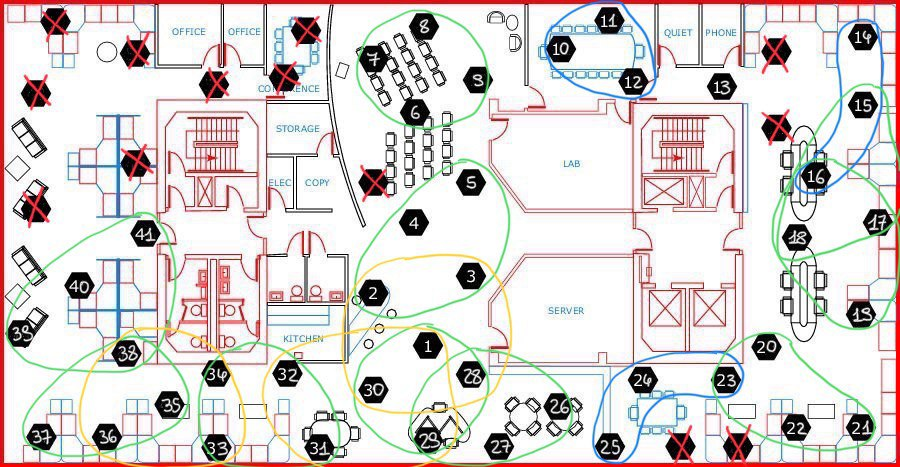

% Carica tutti i dati
load Data.mat

% Numero sensori
num_sensori = 46;

% Variabile: temperatura
j=1;

% Prende tutti i sensori da 1 a 46
for i=1:num_sensori
  
    % Trova le righe di Data che abbiano i come valore della seconda colonna
    S{i}=find(Data(:,2)==i); % cell array, contiene gli indici delle righe 
    x{i,j}=Data(S{i},j+2); % i-esimo sensore, prima variabile (temperatura)

    % Filtraggio e interpolazione dati
    
    % Identifica gli outliers
    detect_x{i,j} = isoutlier(x{i,j});

    % Rimuove gli outliers
    x{i,j}= rmoutliers(x{i,j});  
    
    % Prende le epoch temporali dalla prima riga di Data (dell'i-esimo sensore)
    t{i,j}=Data(S{i},1);
   
    % Toglie quelle che corrispondono agli outliers
    t{i,j}=t{i,j}(~detect_x{i,j});
    
    % Toglie i doppioni
    [tu{i,j},IA,IC] = unique(t{i,j});
   
    % Prende i corrispettivi valori della variabile in base alle epoch
    xu{i,j}=x{i,j}(IA);

    % Interpola i valori della variabile con la risoluzione voluta
    xint{i,j} = interp1(tu{i,j}, xu{i,j}, [1:10:6e4]);
end

% Elenco dei sensori da escludere
sensori_da_escludere = [5 15 18 26 28];

% controllo: size(xint{1, 1})

% Numero di punti temporali
num_punti_temporali = length(xint{1, 1});  % Lunghezza del primo vettore colonna (variabile temperatura)
                                           % del primo sensore (è uguale per tutti)
                                           
% Prealloca la matrice (nulla) per contenere le misure della prima colonna di ciascun sensore

% Riduciamo il numero di righe in base ai sensori da escludere
num_sensori_inclusi = num_sensori - length(sensori_da_escludere);
matrice_misure = zeros(num_sensori_inclusi, num_punti_temporali);

% Indice per le righe della matrice
indice_riga = 1;

% Ciclo su ciascun sensore per estrarre i dati della prima colonna
for k = 1:num_sensori
    % Controlla se il sensore è nella lista da escludere
    if ismember(k, sensori_da_escludere)
        continue;  % Salta al prossimo sensore se è da escludere
    end

    % Estrai la prima variabile (temperatura) del sensore k
    vettore_riga = xint{k, 1}(1, :);

    % Inserisci il vettore riga nella riga corrispondente della matrice
    matrice_misure(indice_riga, :) = vettore_riga;

    % Incrementa l'indice della riga
    indice_riga = indice_riga + 1;
end

# Eliminazione valori NaN tramite sostituzione con il valore medio della serie temporale + calcolo varianza

% Inizializzazione degli array per le medie e le varianze
medie = zeros(41, 1);
varianze = zeros(41, 1);
dev_stand = zeros(41, 1);

% Calcolo della media e della varianza per ogni riga
for l = 1:num_sensori_inclusi
    medie(l) = mean(matrice_misure(l, :), 'omitnan');  % Calcola la media ignorando NaN
    varianze(l) = var(matrice_misure(l, :), 'omitnan'); % Calcola la varianza ignorando NaN
    dev_stand(l) = sqrt(varianze(l));
end

for k = 1:num_sensori_inclusi % Ciclo attraverso ogni sensore
    for l = 1:num_punti_temporali % Ciclo attraverso ogni punto temporale
        if isnan(matrice_misure(k, l)) % Controlla se il valore è NaN
            matrice_misure(k,l) = medie(k,1);  % Sostituisce NaN con la media del sensore           
        end
    end
end

# Raggruppamenti a 3 sensori

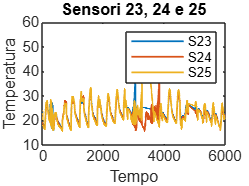

% Diagramma temporale: temperatura

% Selezione dei sensori da plottare
sensori = [23, 24, 25];  % Indici delle righe nella matrice_misure

% Grafico generale per tutti e tre i sensori
figure; % Crea una nuova finestra grafica
plot(matrice_misure(sensori, :)', 'LineWidth', 1); % Plotta l'andamento temporale del gruppo di sensori
title('Sensori 23, 24 e 25')
legend('S23', 'S24', 'S25')
xlabel('Tempo')
ylabel('Temperatura')

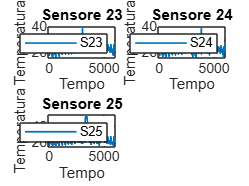

% Sottopannelli per ciascun sensore
subplot(2, 2, 1); % Posizione 1 della griglia 2x2
plot(matrice_misure(sensori(1), :), 'LineWidth', 1); % Plotta solo il sensore 23
title(['Sensore ', num2str(sensori(1))])
legend(['S', num2str(sensori(1))])
xlabel('Tempo')
ylabel('Temperatura')

subplot(2, 2, 2); % Posizione 2 della griglia 2x2
plot(matrice_misure(sensori(2), :), 'LineWidth', 1); % Plotta solo il sensore 24
title(['Sensore ', num2str(sensori(2))])
legend(['S', num2str(sensori(2))])
xlabel('Tempo')
ylabel('Temperatura')

subplot(2, 2, 3); % Posizione 3 della griglia 2x2
plot(matrice_misure(sensori(3), :), 'LineWidth', 1); % Plotta solo il sensore 25
title(['Sensore ', num2str(sensori(3))])
legend(['S', num2str(sensori(3))])
xlabel('Tempo')
ylabel('Temperatura')


clf; % Pulisce la finestra grafica

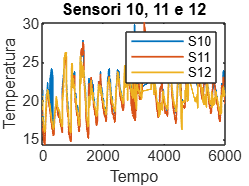

% Selezione dei sensori da plottare
sensori = [10, 11, 12];  % Indici delle righe nella matrice_misure

% Grafico generale per tutti e tre i sensori
figure; % Crea una nuova finestra grafica
plot(matrice_misure(sensori, :)', 'LineWidth', 1); % Plotta l'andamento temporale del gruppo di sensori
title('Sensori 10, 11 e 12')
legend('S10', 'S11', 'S12')
xlabel('Tempo')
ylabel('Temperatura')

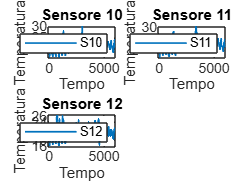

% Sottopannelli per ciascun sensore
subplot(2, 2, 1); % Posizione 1 della griglia 2x2
plot(matrice_misure(sensori(1), :), 'LineWidth', 1); % Plotta solo il sensore 10
title(['Sensore ', num2str(sensori(1))])
legend(['S', num2str(sensori(1))])
xlabel('Tempo')
ylabel('Temperatura')

subplot(2, 2, 2); % Posizione 2 della griglia 2x2
plot(matrice_misure(sensori(2), :), 'LineWidth', 1); % Plotta solo il sensore 11
title(['Sensore ', num2str(sensori(2))])
legend(['S', num2str(sensori(2))])
xlabel('Tempo')
ylabel('Temperatura')

subplot(2, 2, 3); % Posizione 3 della griglia 2x2
plot(matrice_misure(sensori(3), :), 'LineWidth', 1); % Plotta solo il sensore 12
title(['Sensore ', num2str(sensori(3))])
legend(['S', num2str(sensori(3))])
xlabel('Tempo')
ylabel('Temperatura')


clf; % Pulisce la finestra grafica

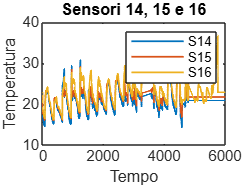

% Selezione dei sensori da plottare
sensori = [14, 15, 16];  % Indici delle righe nella matrice_misure

% Grafico generale per tutti e tre i sensori
figure; % Crea una nuova finestra grafica
plot(matrice_misure(sensori, :)', 'LineWidth', 1); % Plotta l'andamento temporale del gruppo di sensori
title('Sensori 14, 15 e 16')
legend('S14', 'S15', 'S16')
xlabel('Tempo')
ylabel('Temperatura')

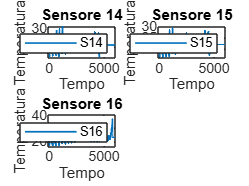

% Sottopannelli per ciascun sensore
subplot(2, 2, 1); % Posizione 1 della griglia 2x2
plot(matrice_misure(sensori(1), :), 'LineWidth', 1); % Plotta solo il sensore 14
title(['Sensore ', num2str(sensori(1))])
legend(['S', num2str(sensori(1))])
xlabel('Tempo')
ylabel('Temperatura')

subplot(2, 2, 2); % Posizione 2 della griglia 2x2
plot(matrice_misure(sensori(2), :), 'LineWidth', 1); % Plotta solo il sensore 15
title(['Sensore ', num2str(sensori(2))])
legend(['S', num2str(sensori(2))])
xlabel('Tempo')
ylabel('Temperatura')

subplot(2, 2, 3); % Posizione 3 della griglia 2x2
plot(matrice_misure(sensori(3), :), 'LineWidth', 1); % Plotta solo il sensore 16
title(['Sensore ', num2str(sensori(3))])
legend(['S', num2str(sensori(3))])
xlabel('Tempo')
ylabel('Temperatura')


clf; % Pulisce la finestra grafica

# Raggruppamenti a 4 sensori

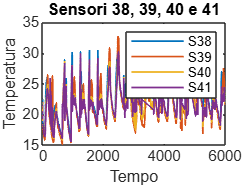

% Selezione dei sensori da plottare
sensori = [38, 39, 40, 41];  % Indici delle righe nella matrice_misure

% Grafico generale per tutti e quattro i sensori
figure; % Crea una nuova finestra grafica
plot(matrice_misure(sensori, :)', 'LineWidth', 1); % Plotta l'andamento temporale del gruppo di sensori
title('Sensori 38, 39, 40 e 41')
legend('S38', 'S39', 'S40', 'S41')
xlabel('Tempo')
ylabel('Temperatura')

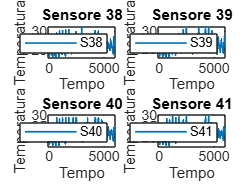


% Sottopannelli per ciascun sensore
subplot(2, 2, 1); % Posizione 1 della griglia 2x2
plot(matrice_misure(sensori(1), :), 'LineWidth', 1); % Plotta solo il sensore 38
title(['Sensore ', num2str(sensori(1))])
legend(['S', num2str(sensori(1))])
xlabel('Tempo')
ylabel('Temperatura')

subplot(2, 2, 2); % Posizione 2 della griglia 2x2
plot(matrice_misure(sensori(2), :), 'LineWidth', 1); % Plotta solo il sensore 39
title(['Sensore ', num2str(sensori(2))])
legend(['S', num2str(sensori(2))])
xlabel('Tempo')
ylabel('Temperatura')

subplot(2, 2, 3); % Posizione 3 della griglia 2x2
plot(matrice_misure(sensori(3), :), 'LineWidth', 1); % Plotta solo il sensore 40
title(['Sensore ', num2str(sensori(3))])
legend(['S', num2str(sensori(3))])
xlabel('Tempo')
ylabel('Temperatura')

subplot(2, 2, 4); % Posizione 4 della griglia 2x2
plot(matrice_misure(sensori(4), :), 'LineWidth', 1); % Plotta solo il sensore 41
title(['Sensore ', num2str(sensori(4))])
legend(['S', num2str(sensori(4))])
xlabel('Tempo')
ylabel('Temperatura')


clf; % Pulisce la finestra grafica

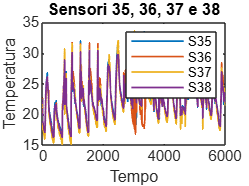

% Selezione dei sensori da plottare
sensori = [35, 36, 37, 38];  % Indici delle righe nella matrice_misure

% Grafico generale per tutti e quattro i sensori
figure; % Crea una nuova finestra grafica
plot(matrice_misure(sensori, :)', 'LineWidth', 1); % Plotta l'andamento temporale del gruppo di sensori
title('Sensori 35, 36, 37 e 38')
legend('S35', 'S36', 'S37', 'S38')
xlabel('Tempo')
ylabel('Temperatura')

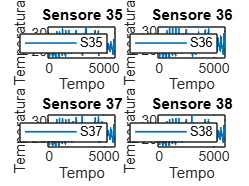


% Sottopannelli per ciascun sensore
subplot(2, 2, 1); % Posizione 1 della griglia 2x2
plot(matrice_misure(sensori(1), :), 'LineWidth', 1); % Plotta solo il sensore 35
title(['Sensore ', num2str(sensori(1))])
legend(['S', num2str(sensori(1))])
xlabel('Tempo')
ylabel('Temperatura')

subplot(2, 2, 2); % Posizione 2 della griglia 2x2
plot(matrice_misure(sensori(2), :), 'LineWidth', 1); % Plotta solo il sensore 36
title(['Sensore ', num2str(sensori(2))])
legend(['S', num2str(sensori(2))])
xlabel('Tempo')
ylabel('Temperatura')

subplot(2, 2, 3); % Posizione 3 della griglia 2x2
plot(matrice_misure(sensori(3), :), 'LineWidth', 1); % Plotta solo il sensore 37
title(['Sensore ', num2str(sensori(3))])
legend(['S', num2str(sensori(3))])
xlabel('Tempo')
ylabel('Temperatura')

subplot(2, 2, 4); % Posizione 4 della griglia 2x2
plot(matrice_misure(sensori(4), :), 'LineWidth', 1); % Plotta solo il sensore 38
title(['Sensore ', num2str(sensori(4))])
legend(['S', num2str(sensori(4))])
xlabel('Tempo')
ylabel('Temperatura')


clf; % Pulisce la finestra grafica

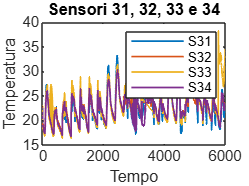

% Selezione dei sensori da plottare
sensori = [31, 32, 33, 34];  % Indici delle righe nella matrice_misure

% Grafico generale per tutti e quattro i sensori
figure; % Crea una nuova finestra grafica
plot(matrice_misure(sensori, :)', 'LineWidth', 1); % Plotta l'andamento temporale del gruppo di sensori
title('Sensori 31, 32, 33 e 34')
legend('S31', 'S32', 'S33', 'S34')
xlabel('Tempo')
ylabel('Temperatura')

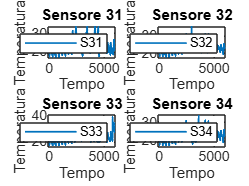


% Sottopannelli per ciascun sensore
subplot(2, 2, 1); % Posizione 1 della griglia 2x2
plot(matrice_misure(sensori(1), :), 'LineWidth', 1); % Plotta solo il sensore 31
title(['Sensore ', num2str(sensori(1))])
legend(['S', num2str(sensori(1))])
xlabel('Tempo')
ylabel('Temperatura')

subplot(2, 2, 2); % Posizione 2 della griglia 2x2
plot(matrice_misure(sensori(2), :), 'LineWidth', 1); % Plotta solo il sensore 32
title(['Sensore ', num2str(sensori(2))])
legend(['S', num2str(sensori(2))])
xlabel('Tempo')
ylabel('Temperatura')

subplot(2, 2, 3); % Posizione 3 della griglia 2x2
plot(matrice_misure(sensori(3), :), 'LineWidth', 1); % Plotta solo il sensore 33
title(['Sensore ', num2str(sensori(3))])
legend(['S', num2str(sensori(3))])
xlabel('Tempo')
ylabel('Temperatura')

subplot(2, 2, 4); % Posizione 4 della griglia 2x2
plot(matrice_misure(sensori(4), :), 'LineWidth', 1); % Plotta solo il sensore 34
title(['Sensore ', num2str(sensori(4))])
legend(['S', num2str(sensori(4))])
xlabel('Tempo')
ylabel('Temperatura')


% Pulisce la finestra grafica
clf;

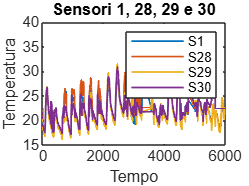

% Selezione dei sensori da plottare
sensori = [1, 28, 29, 30];  % Indici delle righe nella matrice_misure

% Grafico generale per tutti e quattro i sensori
figure; % Crea una nuova finestra grafica
plot(matrice_misure(sensori, :)', 'LineWidth', 1); % Plotta l'andamento temporale del gruppo di sensori
title('Sensori 1, 28, 29 e 30')
legend('S1', 'S28', 'S29', 'S30')
xlabel('Tempo')
ylabel('Temperatura')

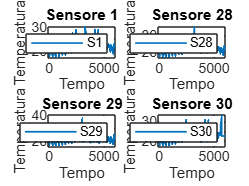


% Sottopannelli per ciascun sensore
subplot(2, 2, 1); % Posizione 1 della griglia 2x2
plot(matrice_misure(sensori(1), :), 'LineWidth', 1); % Plotta solo il sensore 1
title(['Sensore ', num2str(sensori(1))])
legend(['S', num2str(sensori(1))])
xlabel('Tempo')
ylabel('Temperatura')

subplot(2, 2, 2); % Posizione 2 della griglia 2x2
plot(matrice_misure(sensori(2), :), 'LineWidth', 1); % Plotta solo il sensore 28
title(['Sensore ', num2str(sensori(2))])
legend(['S', num2str(sensori(2))])
xlabel('Tempo')
ylabel('Temperatura')

subplot(2, 2, 3); % Posizione 3 della griglia 2x2
plot(matrice_misure(sensori(3), :), 'LineWidth', 1); % Plotta solo il sensore 29
title(['Sensore ', num2str(sensori(3))])
legend(['S', num2str(sensori(3))])
xlabel('Tempo')
ylabel('Temperatura')

subplot(2, 2, 4); % Posizione 4 della griglia 2x2
plot(matrice_misure(sensori(4), :), 'LineWidth', 1); % Plotta solo il sensore 30
title(['Sensore ', num2str(sensori(4))])
legend(['S', num2str(sensori(4))])
xlabel('Tempo')
ylabel('Temperatura')


% Pulisce la finestra grafica
clf;

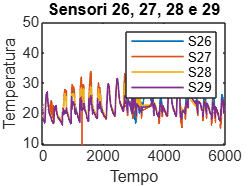

% Selezione dei sensori da plottare
sensori = [26, 27, 28, 29];  % Indici delle righe nella matrice_misure

% Grafico generale per tutti e quattro i sensori
figure; % Crea una nuova finestra grafica
plot(matrice_misure(sensori, :)', 'LineWidth', 1); % Plotta l'andamento temporale del gruppo di sensori
title('Sensori 26, 27, 28 e 29')
legend('S26', 'S27', 'S28', 'S29')
xlabel('Tempo')
ylabel('Temperatura')

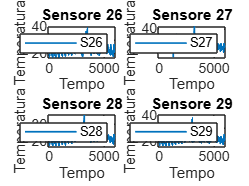


% Sottopannelli per ciascun sensore
subplot(2, 2, 1); % Posizione 1 della griglia 2x2
plot(matrice_misure(sensori(1), :), 'LineWidth', 1); % Plotta solo il sensore 26
title(['Sensore ', num2str(sensori(1))])
legend(['S', num2str(sensori(1))])
xlabel('Tempo')
ylabel('Temperatura')

subplot(2, 2, 2); % Posizione 2 della griglia 2x2
plot(matrice_misure(sensori(2), :), 'LineWidth', 1); % Plotta solo il sensore 27
title(['Sensore ', num2str(sensori(2))])
legend(['S', num2str(sensori(2))])
xlabel('Tempo')
ylabel('Temperatura')

subplot(2, 2, 3); % Posizione 3 della griglia 2x2
plot(matrice_misure(sensori(3), :), 'LineWidth', 1); % Plotta solo il sensore 28
title(['Sensore ', num2str(sensori(3))])
legend(['S', num2str(sensori(3))])
xlabel('Tempo')
ylabel('Temperatura')

subplot(2, 2, 4); % Posizione 4 della griglia 2x2
plot(matrice_misure(sensori(4), :), 'LineWidth', 1); % Plotta solo il sensore 29
title(['Sensore ', num2str(sensori(4))])
legend(['S', num2str(sensori(4))])
xlabel('Tempo')
ylabel('Temperatura')


% Pulisce la finestra grafica
clf;

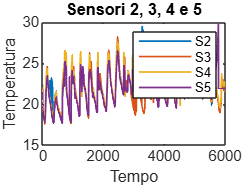

% Selezione dei sensori da plottare
sensori = [2, 3, 4, 5];  % Indici delle righe nella matrice_misure

% Grafico generale per tutti e quattro i sensori
figure; % Crea una nuova finestra grafica
plot(matrice_misure(sensori, :)', 'LineWidth', 1); % Plotta l'andamento temporale del gruppo di sensori
title('Sensori 2, 3, 4 e 5')
legend('S2', 'S3', 'S4', 'S5')
xlabel('Tempo')
ylabel('Temperatura')

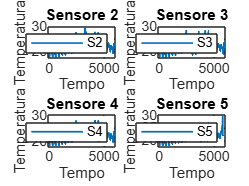


% Sottopannelli per ciascun sensore
subplot(2, 2, 1); % Posizione 1 della griglia 2x2
plot(matrice_misure(sensori(1), :), 'LineWidth', 1); % Plotta solo il sensore 2
title(['Sensore ', num2str(sensori(1))])
legend(['S', num2str(sensori(1))])
xlabel('Tempo')
ylabel('Temperatura')

subplot(2, 2, 2); % Posizione 2 della griglia 2x2
plot(matrice_misure(sensori(2), :), 'LineWidth', 1); % Plotta solo il sensore 3
title(['Sensore ', num2str(sensori(2))])
legend(['S', num2str(sensori(2))])
xlabel('Tempo')
ylabel('Temperatura')

subplot(2, 2, 3); % Posizione 3 della griglia 2x2
plot(matrice_misure(sensori(3), :), 'LineWidth', 1); % Plotta solo il sensore 4
title(['Sensore ', num2str(sensori(3))])
legend(['S', num2str(sensori(3))])
xlabel('Tempo')
ylabel('Temperatura')

subplot(2, 2, 4); % Posizione 4 della griglia 2x2
plot(matrice_misure(sensori(4), :), 'LineWidth', 1); % Plotta solo il sensore 5
title(['Sensore ', num2str(sensori(4))])
legend(['S', num2str(sensori(4))])
xlabel('Tempo')
ylabel('Temperatura')


% Pulisce la finestra grafica
clf;

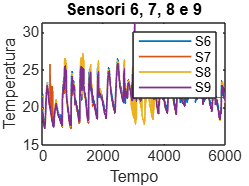

% Selezione dei sensori da plottare
sensori = [6, 7, 8, 9];  % Indici delle righe nella matrice_misure

% Grafico generale per tutti e quattro i sensori
figure; % Crea una nuova finestra grafica
plot(matrice_misure(sensori, :)', 'LineWidth', 1); % Plotta l'andamento temporale del gruppo di sensori
title('Sensori 6, 7, 8 e 9')
legend('S6', 'S7', 'S8', 'S9')
xlabel('Tempo')
ylabel('Temperatura')

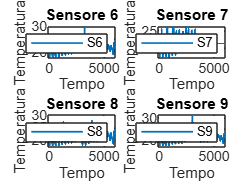


% Sottopannelli per ciascun sensore
subplot(2, 2, 1); % Posizione 1 della griglia 2x2
plot(matrice_misure(sensori(1), :), 'LineWidth', 1); % Plotta solo il sensore 6
title(['Sensore ', num2str(sensori(1))])
legend(['S', num2str(sensori(1))])
xlabel('Tempo')
ylabel('Temperatura')

subplot(2, 2, 2); % Posizione 2 della griglia 2x2
plot(matrice_misure(sensori(2), :), 'LineWidth', 1); % Plotta solo il sensore 7
title(['Sensore ', num2str(sensori(2))])
legend(['S', num2str(sensori(2))])
xlabel('Tempo')
ylabel('Temperatura')

subplot(2, 2, 3); % Posizione 3 della griglia 2x2
plot(matrice_misure(sensori(3), :), 'LineWidth', 1); % Plotta solo il sensore 8
title(['Sensore ', num2str(sensori(3))])
legend(['S', num2str(sensori(3))])
xlabel('Tempo')
ylabel('Temperatura')

subplot(2, 2, 4); % Posizione 4 della griglia 2x2
plot(matrice_misure(sensori(4), :), 'LineWidth', 1); % Plotta solo il sensore 9
title(['Sensore ', num2str(sensori(4))])
legend(['S', num2str(sensori(4))])
xlabel('Tempo')
ylabel('Temperatura')


% Pulisce la finestra grafica
clf;

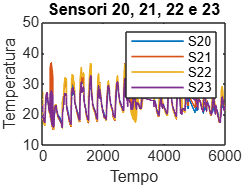

% Selezione dei sensori da plottare
sensori = [20, 21, 22, 23];  % Indici delle righe nella matrice_misure

% Grafico generale per tutti e quattro i sensori
figure; % Crea una nuova finestra grafica
plot(matrice_misure(sensori, :)', 'LineWidth', 1); % Plotta l'andamento temporale del gruppo di sensori
title('Sensori 20, 21, 22 e 23')
legend('S20', 'S21', 'S22', 'S23')
xlabel('Tempo')
ylabel('Temperatura')

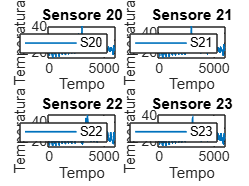


% Sottopannelli per ciascun sensore
subplot(2, 2, 1); % Posizione 1 della griglia 2x2
plot(matrice_misure(sensori(1), :), 'LineWidth', 1); % Plotta solo il sensore 20
title(['Sensore ', num2str(sensori(1))])
legend(['S', num2str(sensori(1))])
xlabel('Tempo')
ylabel('Temperatura')

subplot(2, 2, 2); % Posizione 2 della griglia 2x2
plot(matrice_misure(sensori(2), :), 'LineWidth', 1); % Plotta solo il sensore 21
title(['Sensore ', num2str(sensori(2))])
legend(['S', num2str(sensori(2))])
xlabel('Tempo')
ylabel('Temperatura')

subplot(2, 2, 3); % Posizione 3 della griglia 2x2
plot(matrice_misure(sensori(3), :), 'LineWidth', 1); % Plotta solo il sensore 22
title(['Sensore ', num2str(sensori(3))])
legend(['S', num2str(sensori(3))])
xlabel('Tempo')
ylabel('Temperatura')

subplot(2, 2, 4); % Posizione 4 della griglia 2x2
plot(matrice_misure(sensori(4), :), 'LineWidth', 1); % Plotta solo il sensore 23
title(['Sensore ', num2str(sensori(4))])
legend(['S', num2str(sensori(4))])
xlabel('Tempo')
ylabel('Temperatura')


% Pulisce la finestra grafica
clf;

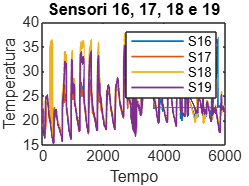

% Selezione dei sensori da plottare
sensori = [16, 17, 18, 19];  % Indici delle righe nella matrice_misure

% Grafico generale per tutti e quattro i sensori
figure; % Crea una nuova finestra grafica
plot(matrice_misure(sensori, :)', 'LineWidth', 1); % Plotta l'andamento temporale del gruppo di sensori
title('Sensori 16, 17, 18 e 19')
legend('S16', 'S17', 'S18', 'S19')
xlabel('Tempo')
ylabel('Temperatura')

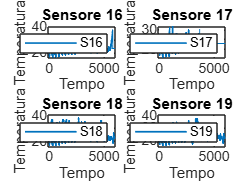


% Sottopannelli per ciascun sensore
subplot(2, 2, 1); % Posizione 1 della griglia 2x2
plot(matrice_misure(sensori(1), :), 'LineWidth', 1); % Plotta solo il sensore 16
title(['Sensore ', num2str(sensori(1))])
legend(['S', num2str(sensori(1))])
xlabel('Tempo')
ylabel('Temperatura')

subplot(2, 2, 2); % Posizione 2 della griglia 2x2
plot(matrice_misure(sensori(2), :), 'LineWidth', 1); % Plotta solo il sensore 17
title(['Sensore ', num2str(sensori(2))])
legend(['S', num2str(sensori(2))])
xlabel('Tempo')
ylabel('Temperatura')

subplot(2, 2, 3); % Posizione 3 della griglia 2x2
plot(matrice_misure(sensori(3), :), 'LineWidth', 1); % Plotta solo il sensore 18
title(['Sensore ', num2str(sensori(3))])
legend(['S', num2str(sensori(3))])
xlabel('Tempo')
ylabel('Temperatura')

subplot(2, 2, 4); % Posizione 4 della griglia 2x2
plot(matrice_misure(sensori(4), :), 'LineWidth', 1); % Plotta solo il sensore 19
title(['Sensore ', num2str(sensori(4))])
legend(['S', num2str(sensori(4))])
xlabel('Tempo')
ylabel('Temperatura')


% Pulisce la finestra grafica
clf;

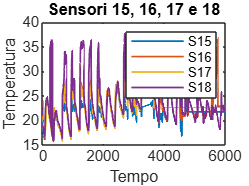

% Selezione dei sensori da plottare
sensori = [15, 16, 17, 18];  % Indici delle righe nella matrice_misure

% Grafico generale per tutti e quattro i sensori
figure; % Crea una nuova finestra grafica
plot(matrice_misure(sensori, :)', 'LineWidth', 1); % Plotta l'andamento temporale del gruppo di sensori
title('Sensori 15, 16, 17 e 18')
legend('S15', 'S16', 'S17', 'S18')
xlabel('Tempo')
ylabel('Temperatura')

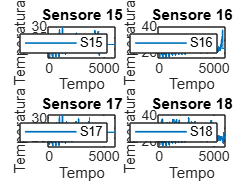


% Sottopannelli per ciascun sensore
subplot(2, 2, 1); % Posizione 1 della griglia 2x2
plot(matrice_misure(sensori(1), :), 'LineWidth', 1); % Plotta solo il sensore 15
title(['Sensore ', num2str(sensori(1))])
legend(['S', num2str(sensori(1))])
xlabel('Tempo')
ylabel('Temperatura')

subplot(2, 2, 2); % Posizione 2 della griglia 2x2
plot(matrice_misure(sensori(2), :), 'LineWidth', 1); % Plotta solo il sensore 16
title(['Sensore ', num2str(sensori(2))])
legend(['S', num2str(sensori(2))])
xlabel('Tempo')
ylabel('Temperatura')

subplot(2, 2, 3); % Posizione 3 della griglia 2x2
plot(matrice_misure(sensori(3), :), 'LineWidth', 1); % Plotta solo il sensore 17
title(['Sensore ', num2str(sensori(3))])
legend(['S', num2str(sensori(3))])
xlabel('Tempo')
ylabel('Temperatura')

subplot(2, 2, 4); % Posizione 4 della griglia 2x2
plot(matrice_misure(sensori(4), :), 'LineWidth', 1); % Plotta solo il sensore 18
title(['Sensore ', num2str(sensori(4))])
legend(['S', num2str(sensori(4))])
xlabel('Tempo')
ylabel('Temperatura')


% Pulisce la finestra grafica
clf;

# Raggruppamenti a 5 sensori

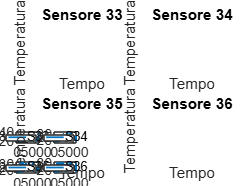

% Selezione dei sensori da plottare
sensori = [33, 34, 35, 36, 38];  % Indici delle righe nella matrice_misure

% Grafico generale per i primi 4 sensori (sottopannelli)
figure; % Crea una nuova finestra grafica

% Sottopannelli per ciascun sensore (4 sensori)
subplot(2, 2, 1); % Posizione 1 della griglia 2x2
plot(matrice_misure(sensori(1), :), 'LineWidth', 1); % Plotta solo il sensore 33
title(['Sensore ', num2str(sensori(1))])
legend(['S', num2str(sensori(1))])
xlabel('Tempo')
ylabel('Temperatura')

subplot(2, 2, 2); % Posizione 2 della griglia 2x2
plot(matrice_misure(sensori(2), :), 'LineWidth', 1); % Plotta solo il sensore 34
title(['Sensore ', num2str(sensori(2))])
legend(['S', num2str(sensori(2))])
xlabel('Tempo')
ylabel('Temperatura')

subplot(2, 2, 3); % Posizione 3 della griglia 2x2
plot(matrice_misure(sensori(3), :), 'LineWidth', 1); % Plotta solo il sensore 35
title(['Sensore ', num2str(sensori(3))])
legend(['S', num2str(sensori(3))])
xlabel('Tempo')
ylabel('Temperatura')

subplot(2, 2, 4); % Posizione 4 della griglia 2x2
plot(matrice_misure(sensori(4), :), 'LineWidth', 1); % Plotta solo il sensore 36
title(['Sensore ', num2str(sensori(4))])
legend(['S', num2str(sensori(4))])
xlabel('Tempo')
ylabel('Temperatura')

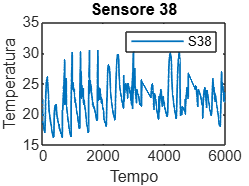


% Grafico separato per l'ultimo sensore
figure; % Crea una nuova finestra grafica
plot(matrice_misure(sensori(5), :), 'LineWidth', 1);
title(['Sensore ', num2str(sensori(5))])
legend(['S', num2str(sensori(5))])
xlabel('Tempo')
ylabel('Temperatura')


% Pulisce la finestra grafica
clf

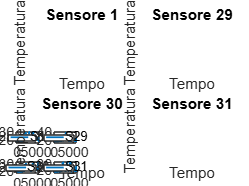

% Selezione dei sensori da plottare
sensori = [1, 29, 30, 31, 32];  % Indici delle righe nella matrice_misure

% Grafico generale per i primi 4 sensori (sottopannelli)
figure; % Crea una nuova finestra grafica

% Sottopannelli per ciascun sensore (4 sensori)
subplot(2, 2, 1); % Posizione 1 della griglia 2x2
plot(matrice_misure(sensori(1), :), 'LineWidth', 1); % Plotta solo il sensore 1
title(['Sensore ', num2str(sensori(1))])
legend(['S', num2str(sensori(1))])
xlabel('Tempo')
ylabel('Temperatura')

subplot(2, 2, 2); % Posizione 2 della griglia 2x2
plot(matrice_misure(sensori(2), :), 'LineWidth', 1); % Plotta solo il sensore 29
title(['Sensore ', num2str(sensori(2))])
legend(['S', num2str(sensori(2))])
xlabel('Tempo')
ylabel('Temperatura')

subplot(2, 2, 3); % Posizione 3 della griglia 2x2
plot(matrice_misure(sensori(3), :), 'LineWidth', 1); % Plotta solo il sensore 30
title(['Sensore ', num2str(sensori(3))])
legend(['S', num2str(sensori(3))])
xlabel('Tempo')
ylabel('Temperatura')

subplot(2, 2, 4); % Posizione 4 della griglia 2x2
plot(matrice_misure(sensori(4), :), 'LineWidth', 1); % Plotta solo il sensore 31
title(['Sensore ', num2str(sensori(4))])
legend(['S', num2str(sensori(4))])
xlabel('Tempo')
ylabel('Temperatura')

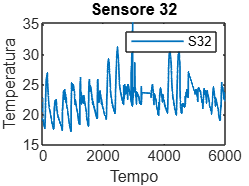


% Grafico separato per l'ultimo sensore
figure; % Crea una nuova finestra grafica
plot(matrice_misure(sensori(5), :), 'LineWidth', 1);
title(['Sensore ', num2str(sensori(5))])
legend(['S', num2str(sensori(5))])
xlabel('Tempo')
ylabel('Temperatura')


% Pulisce la finestra grafica
clf;

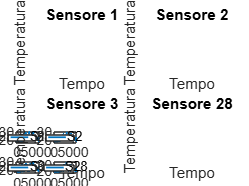

% Selezione dei sensori da plottare
sensori = [1, 2, 3, 28, 30];  % Indici delle righe nella matrice_misure

% Grafico generale per i primi 4 sensori (sottopannelli)
figure; % Crea una nuova finestra grafica

% Sottopannelli per ciascun sensore (4 sensori)
subplot(2, 2, 1); % Posizione 1 della griglia 2x2
plot(matrice_misure(sensori(1), :), 'LineWidth', 1); % Plotta solo il sensore 1
title(['Sensore ', num2str(sensori(1))])
legend(['S', num2str(sensori(1))])
xlabel('Tempo')
ylabel('Temperatura')

subplot(2, 2, 2); % Posizione 2 della griglia 2x2
plot(matrice_misure(sensori(2), :), 'LineWidth', 1); % Plotta solo il sensore 2
title(['Sensore ', num2str(sensori(2))])
legend(['S', num2str(sensori(2))])
xlabel('Tempo')
ylabel('Temperatura')

subplot(2, 2, 3); % Posizione 3 della griglia 2x2
plot(matrice_misure(sensori(3), :), 'LineWidth', 1); % Plotta solo il sensore 3
title(['Sensore ', num2str(sensori(3))])
legend(['S', num2str(sensori(3))])
xlabel('Tempo')
ylabel('Temperatura')

subplot(2, 2, 4); % Posizione 4 della griglia 2x2
plot(matrice_misure(sensori(4), :), 'LineWidth', 1); % Plotta solo il sensore 28
title(['Sensore ', num2str(sensori(4))])
legend(['S', num2str(sensori(4))])
xlabel('Tempo')
ylabel('Temperatura')

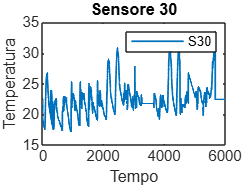


% Grafico separato per l'ultimo sensore
figure; % Crea una nuova finestra grafica
plot(matrice_misure(sensori(5), :), 'LineWidth', 1);
title(['Sensore ', num2str(sensori(5))])
legend(['S', num2str(sensori(5))])
xlabel('Tempo')
ylabel('Temperatura')


% Pulisce la finestra grafica
clf;